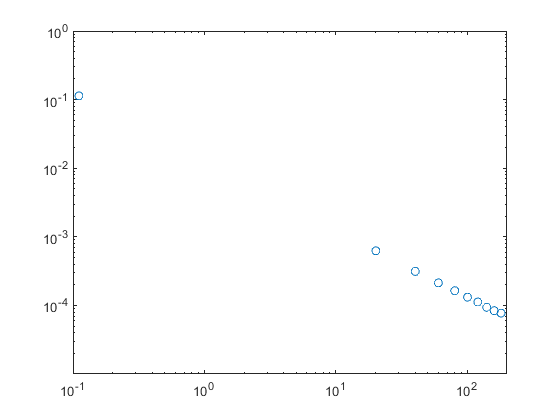

close all;
clear all;

fig1 = openfig('F:\LWT\SensitivityDecayMix.fig');

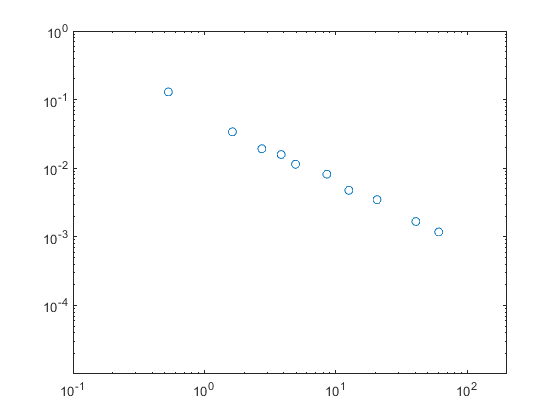

axis1=gca;
CatYdata=axis1.Children.YData;
CatXdata=axis1.Children.XData;

fig2 = openfig('F:\LWT\SensitivityDecayCat.fig');

axis1=gca;
MixYdata=axis1.Children.YData;
MixXdata=axis1.Children.XData;
clear("axis1");

CatYdata=CatYdata*1.2e-6; %Tesla
MixYdata=MixYdata*1.2e-6; %Tesla

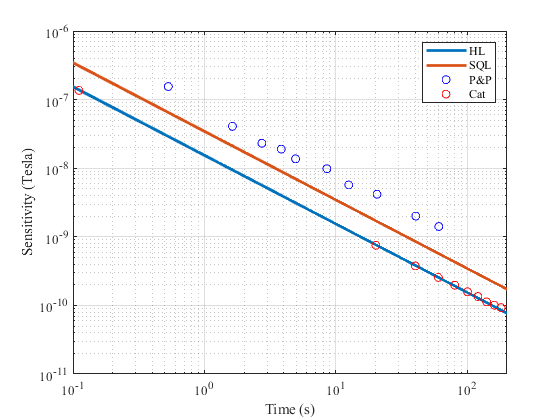

uB = 9.274e-24;
uN = 5.05078375e-27;
gI = -0.271;
hbar = 6.626e-34/(2*pi);
gamma0 = abs(gI*uN/hbar);   % gyromagnetic ratio

F = 5/2;

HL = @(t) 1./t*1/(2*F)*1/gamma0;
SQL = @(t) 1./t*1/sqrt(2*F)*1/gamma0;
timelist = [0.1:0.1:200];

figure;
lineHL = loglog(timelist,HL(timelist));  hold on;
lineSQL = loglog(timelist,SQL(timelist));
set(lineHL,'linewidth',2);
set(lineSQL,'linewidth',2);

scatter(MixXdata,MixYdata,'blue');
scatter(CatXdata,CatYdata,'red');
xlim([0.1 200])
legend("HL","SQL","P&P","Cat");
xlabel("Time (s)");
ylabel("Sensitivity (Tesla)");
set(gca,'fontsize',10,'fontname','times new roman')
set(gcf,'visible','on')
grid on;